# HDC - Visualization and var_sys method

This script is used for the publication titled "**Negotiating System’s Band Broadening in Hydrodynamic Chromatography for the Determination of Particle-Size Distributions of Polymeric Nanoparticles**", authored by J. Verduin, J.D. Kruijswijk et al.

Please first import the matlab dat file titled "HDC_var_sys.mat" in order to run this script.

This script is used for: 

- Visualization of the recorded HDC-UV chromatograms;

- Establishment of a size-calibration curve;

- Determination and visualization of the virtual size and time HDC chromatograms;

- Determination of the system variance (var_sys) and visualization of the corresponding trend line;

- LOOCV to test the bias of the var_sys;

- Visualization of the application of the var_sys approach on PS standards.

% Structurizing the data
% Data set: Simulated_HDC_chromatograms.mat
sigma_t = Standards(:,4)./sqrt(2);       % sigma size = gamma / sqrt(2)

Unrecognized function or variable 'Standards'.

NP_info = [Standards(:,1:4) sigma_t];    % size, sigma_size, tE, gamma, sigma_t

## Virtual chromatograms - size/intensity

% Information Gaussian function
% Gaussian function: 'gauss.m'
%%% chrom = gauss(x,h,u,s)
%%% x = particle size range (0 - 1200 nm)                --> 0 : 0.1 : 1200
%%% h = height                                           --> 1
%%% u = particle size                                    --> PS_info(:,1)
%%% s = particle sigma_size                              --> PS_info(:,2)
x = 0:0.1:1200; % size axis
h = 1;          % peak height of 1

## Certified-size chromatograms

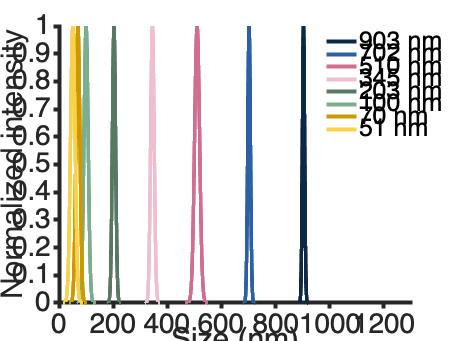

x = 0:0.1:1200; % size axis
% certified size-chromatogram (based on PS vendor specs)
%%% Only plots the last repeat
% Simulated chromatograms PS --> individual colors
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
selection = [50 45 35 25 15 5 40 30];
col_idx = [1 2 3 4 5 6 7 8 9 10];

% PS only
figure
hold on
for i = 1:length(selection)
    plot(x,chrom_norm(selection(i),:), 'LineWidth',2, 'color', colors_list{(i)});
    set(gca, 'FontSize', 14); 
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Normalized intensity'); 
end
xlim([0 1300]);
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northeast');
legend('boxoff')
hold off

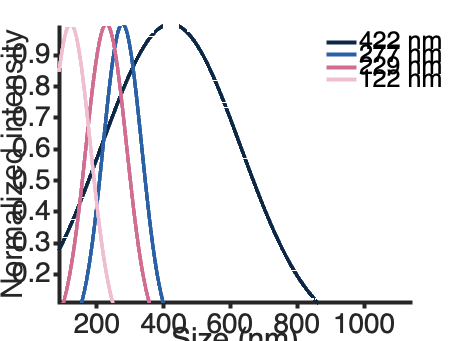


% PLGA only
selection = [62 59 56 53];
figure
hold on
for i = 1:length(selection)
    plot(x,chrom_norm(selection(i),:), 'LineWidth',2, 'color', colors_list{(i)});
    set(gca, 'FontSize', 14); 
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Normalized intensity');
    ylim([0 1.01]);
end
legend('422 nm', '277 nm', '229 nm', '122 nm');
legend('Location','northeast');
legend('boxoff')
hold off

## PS calibration

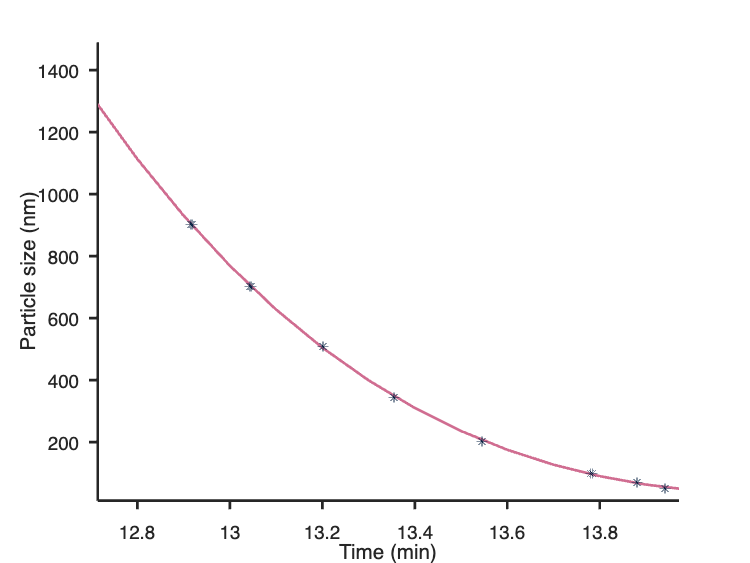

% Indexing the PS samples that will be included in calibration
idx = [true
true
true
true
true
false
false
false
false
false
true
true
true
true
true

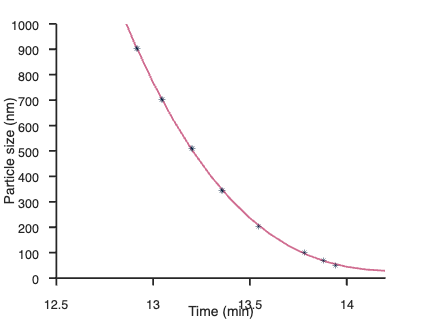

false
false
false
false
false
true
true
true
true
true
true
true
true
true
true
true

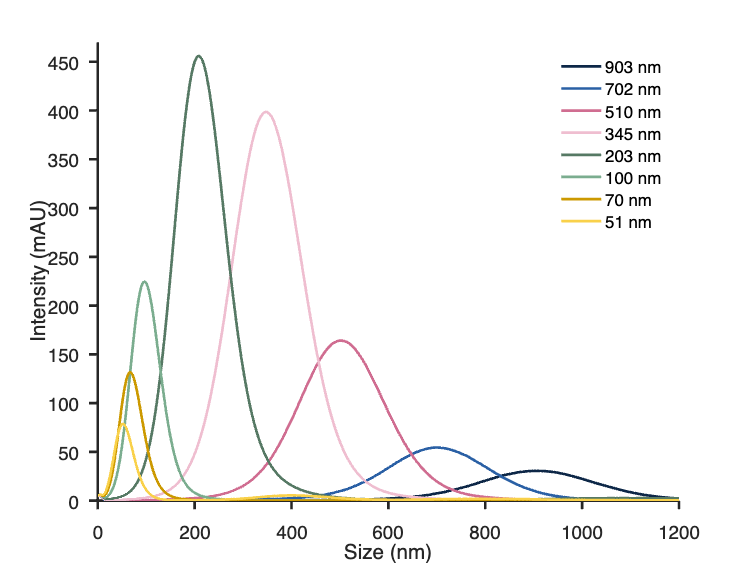

true
true
true
true
true
true
true
true
true
true
true
true
true
true
true
true
true
true
true];


% PS calibration, PS only
colors_list = {'#F9D14A','#0D2747','#2A60A5', '#D06D91','#EFBED0','#567964','#7BAD8F','#FCEFBA'};
p_size = polyfit(NP_info(idx,3),NP_info(idx,1),3); % 3rd order polynomial of time -> size calibration line
time_range = 12.5:0.1:14.5;
figure
hold on
plot(time_range, polyval(p_size, time_range), 'color', colors_list{4}, 'linewidth', 2)
plot(NP_info(idx, 3), NP_info(idx, 1), '*', 'color', colors_list{2}, 'MarkerSize', 7)
xlabel('Time (min)')
ylabel('Particle size (nm)')
%legend('PS calibration curve', 'PS')
%legend('boxoff');
xlim([12.5,14.2]);
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
hold off

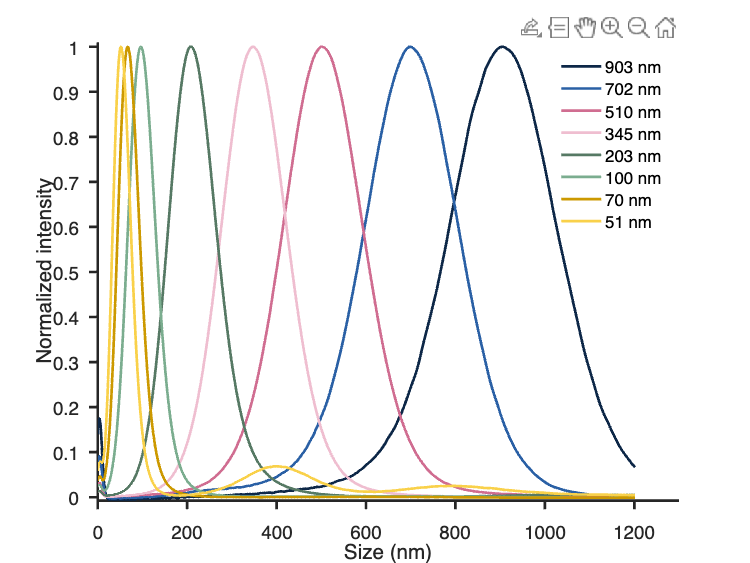

% PS calibration, PS only
colors_list = {'#F9D14A','#0D2747','#2A60A5', '#D06D91','#EFBED0','#567964','#7BAD8F','#FCEFBA'};
p_size = polyfit(NP_info(idx,3),NP_info(idx,1),3); % 3rd order polynomial of time -> size calibration line
time_range = 12.5:0.1:14.5;
figure

hold on
plot(time_range, polyval(p_size, time_range), 'color', colors_list{4}, 'linewidth', 2)
plot(NP_info(idx, 3), NP_info(idx, 1), '*', 'color', colors_list{2}, 'MarkerSize', 7)
xlabel('Time (min)')
ylabel('Particle size (nm)')
xlim([12.5,14.2]);
ylim([0,1000]);
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
hold off

## Size-converted chromatograms

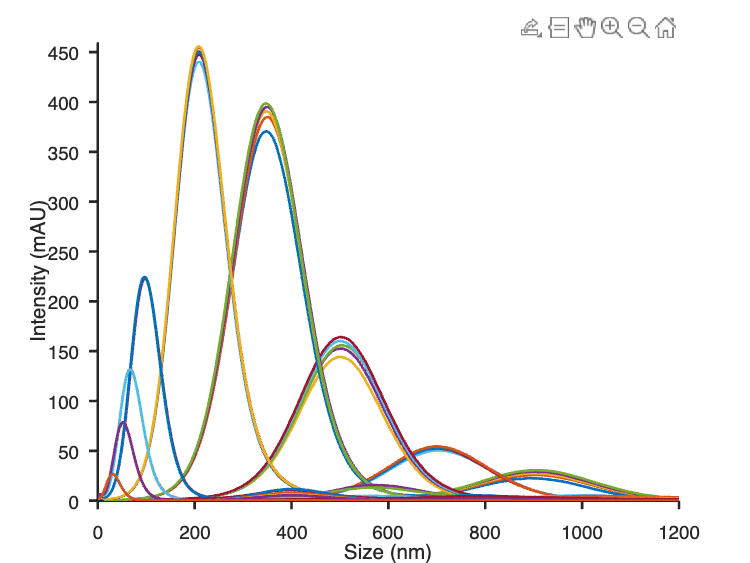

% PS NPs
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
selection = [50 45 35 25 15 5 40 30];
figure
hold on
for i = 1:length(selection)
    PS_size = PSData{selection(i),2};
    plot(PS_size(392:1345,1),PS_size(392:1345,2),'LineWidth',2, 'color', colors_list{(i)})
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    ax = gca; 
    xlabel('Size (nm)'); ylabel('Intensity (mAU)'); 
    xlim([0 1200]);

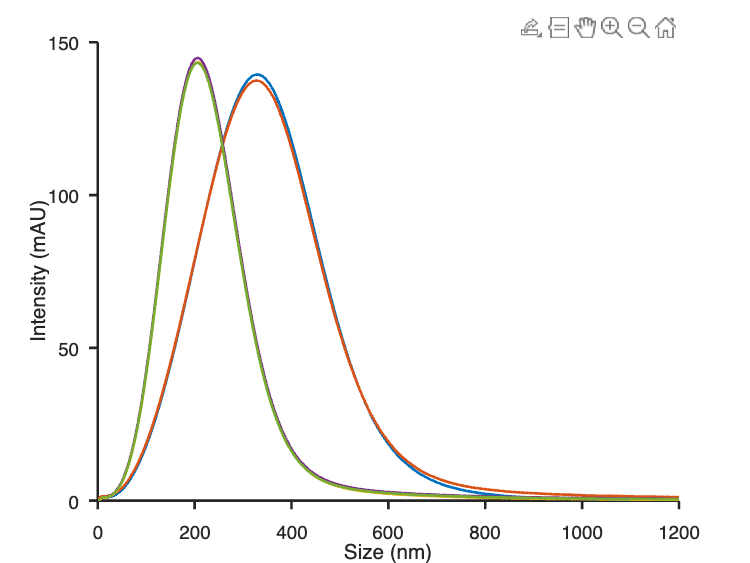

    ylim([0,470]);
end
hold off
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northeast');
legend('boxoff')

PSchrom_size = zeros(1345-391, length(PSData));
for i = 1:length(PSData)
    PS_size = PSData{i,2};
    PSchrom_size(:,i) = PS_size(392:1345,2);
end
PSchrom_size = [PS_size(392:1345,1) PSchrom_size];

colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
selection = [50 45 35 25 15 5 40 30];
figure
hold on
for i = 1:length(selection)

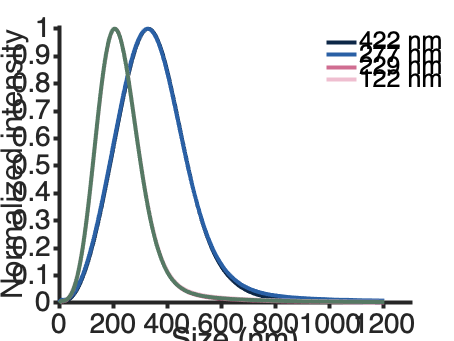

    PS_size_norm = PSData{selection(i),2}./max(PSData{selection(i),2});
    plot(PS_size(392:1345,1),PS_size_norm(392:1345,2),'LineWidth',2, 'color', colors_list{(i)})
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Normalized intensity'); 
    xlim([0 1300]);
    ylim([0,1.01]);
end
hold off
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northeast');
legend('boxoff')

PSchrom_size_norm = zeros(1345-391, length(PSData));
for i = 1:length(PSData)
    PS_size = PSData{i,2};
    PSchrom_size_norm(:,i) = PS_size(392:1345,2);
end

PSchrom_size_norm = [PS_size(392:1345,1) PSchrom_size_norm];


% PS all size chrom
selection = [46 47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30 16 17 18 19 20];
figure
hold on
for i = 1:length(selection)
    PS_size_norm = PSData{selection(i),2};
    plot(PS_size(392:1345,1),PS_size_norm(392:1345,2),'LineWidth',2)
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Intensity (mAU)'); 
    xlim([0 1200]);
    ylim([0,460]);
end

% PLGA NPs
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
selection = [12 9 6 3];

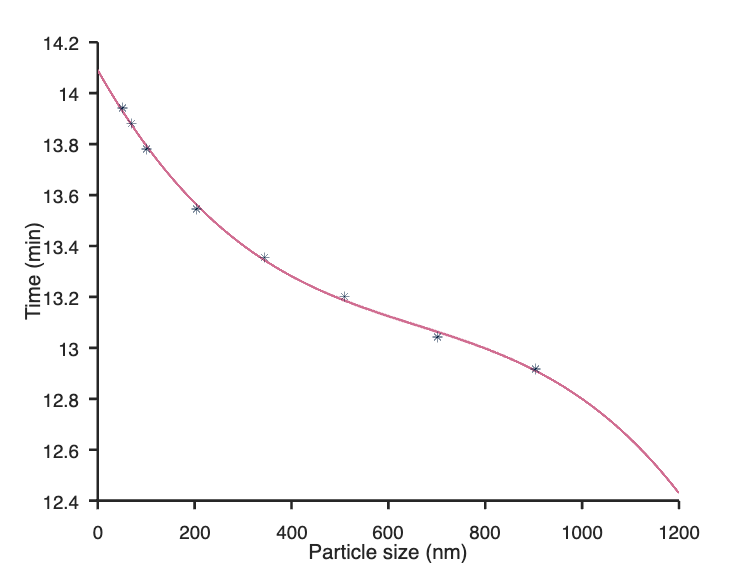

% PLGA all size chrom
figure
hold on
selection = [8 9 4 5 6];
for i = 1:length(selection)
    PLGA_size = DataPLGA{selection(i),2};
    plot(PLGA_size(392:1345,1),PLGA_size(392:1345,2),'LineWidth',2)
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Intensity (mAU)'); 
    xlim([0 1200]);
    ylim([0,150]);

end
hold off

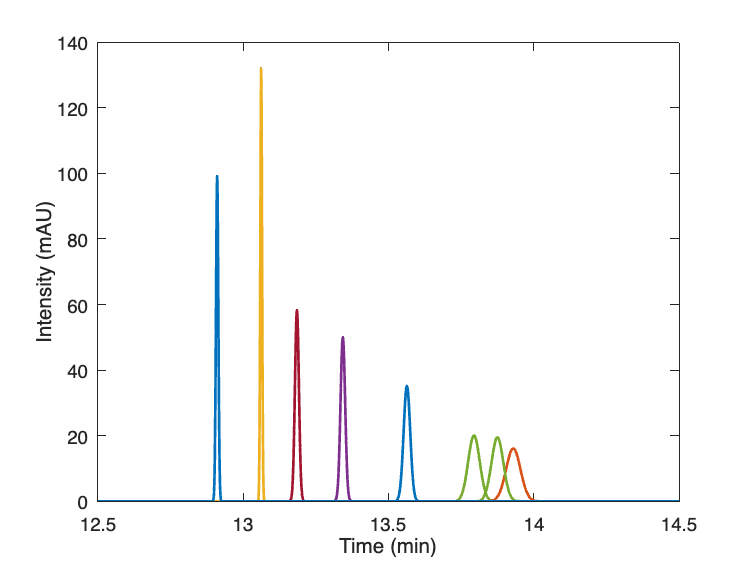

% PLGA time chromatogram
figure
hold on
selection = [8 9 4 5 6];
for i = 1:length(selection)
    PLGA_size_norm = DataPLGA{selection(i),2}./max(DataPLGA{selection(i),2});
    plot(PS_size(392:1345,1),PLGA_size_norm(392:1345,2),'LineWidth',2, 'color', colors_list{(i)})
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Size (nm)'); ylabel('Normalized intensity'); 
    xlim([0 1300]);
    ylim([0,1.01]);
end
hold off
legend('422 nm', '277 nm', '229 nm', '122 nm');
legend('Location','northeast');
legend('boxoff')

PLGAchrom_size_norm = zeros(1345-391, length(DataPLGA));
for i = 1:length(DataPLGA)
    PLGA_size = DataPLGA{i,2};
    PLGAchrom_size_norm(:,i) = PLGA_size_norm(392:1345,2);
end
PLGAchrom_size_norm = [PLGA_size(392:1345,1) PLGAchrom_size_norm];

## Reversed calibration

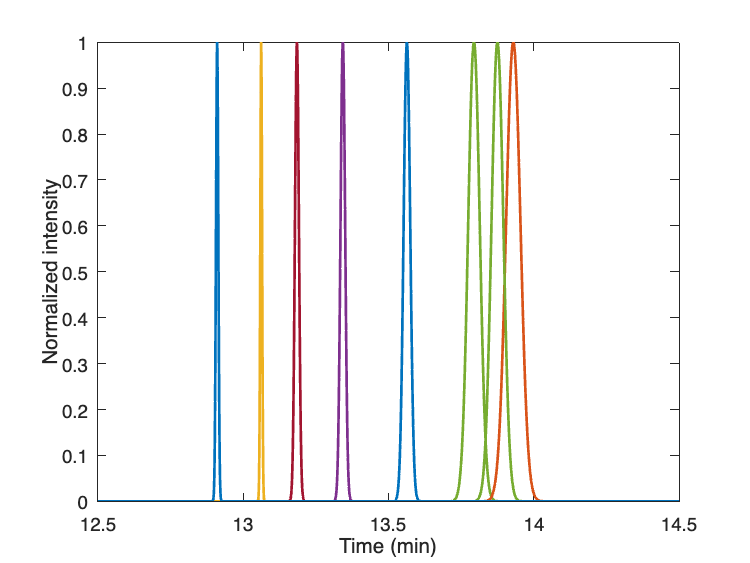

% Reversed calibration
%%% To convert size to time

% Obtain coordinates 
%p_time = polyfit(NP_info(idx,1)/1000,NP_info(idx,3),3);
p_time = polyfit(NP_info(idx,1),NP_info(idx,3),3);%
%aa = -2.108508446277111e-09;
%bb = 4.170602913623963e-06;
%cc = -3.3528;
%dd = 14.0902;

%plot(x,(polyval(p_time, (x.*1000))));
figure
colors_list = {'#F9D14A','#0D2747','#2A60A5', '#D06D91','#EFBED0','#567964','#7BAD8F','#FCEFBA'};

hold on
plot(x,(polyval(p_time, x)), 'color', colors_list{4}, 'linewidth', 2);                 % reversed calibration
plot(NP_info(idx,1),NP_info(idx,3), '*', 'color', colors_list{2}, 'MarkerSize', 7); % PS
hold off
%title('Reversed PS calibration curve')
xlabel('Particle size (nm)')
ylabel('Time (min)')
%legend('Reversed PS calibration curve', 'PS')
%legend('boxoff');
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
hold off


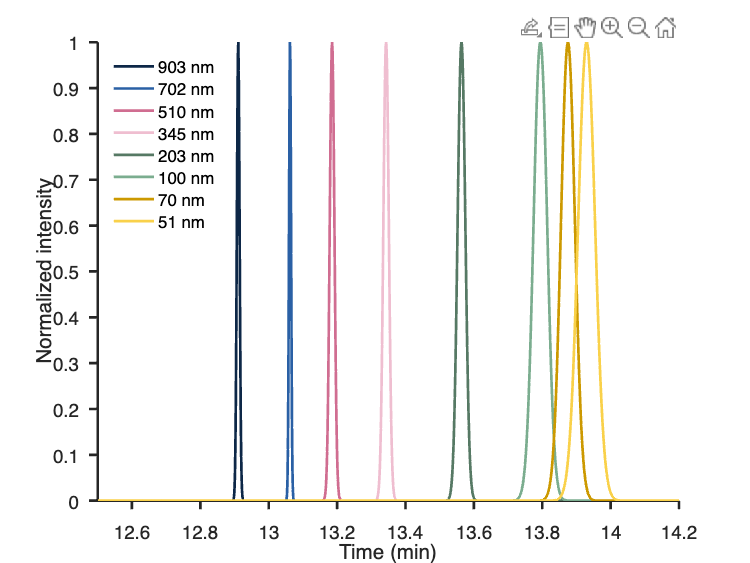

% Conversion peak size to time
% Converts peak width and peak top from size to time with reversed calibration
for i = 1:length(NP_info)
    tops(i) = polyval(p_time,NP_info(i,1));         % NP sizes to time
    base_right(i) = polyval(p_time, (NP_info(i,1)-NP_info(i,2)));   % NP size 2sigma to time sigma
    base_left(i) = polyval(p_time, (NP_info(i,1)+NP_info(i,2)));   % NP size 2sigma to time sigma

    sig_cal(i) = (base_right(i)-base_left(i))./2; % 1 sigma
end
cal_overview = [Standards(:,1),tops' sig_cal];

## Virtual chromatograms - Time/intensity 

% Virtual time-I chromatograms - PS only
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
figure
for i = 1:50
    conv2(i,:) = (gauss(xx,h,tops(i),sig_cal(i)));
    plot(xx,conv2, 'LineWidth',2)
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.5 14.5]);
end
hold on
hold off

% Normalized simulated chromatograms (time)
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
figure
for i = 1:50
    conv2_norm(i,:) = conv2(i,:)./max(conv2(i,:));
    plot(xx,conv2_norm, 'LineWidth',2)
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.5 14.5]);
end
hold on
hold off

% Certified time chromatogram

% Normalized simulated chromatograms (time) --> individual colors
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [50 45 35 25 15 5 40 30];
col_idx = [1 2 3 4 5 6 7 8 9 10];

figure
hold on
for i = 1:length(selection)
    conv2_norm = conv2(selection(i),:)./max(conv2(selection(i),:));
    plot(xx,conv2_norm, 'LineWidth',2, 'color', colors_list{(i)});
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.5 14.2]);
end
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northwest');
legend('boxoff')
hold off

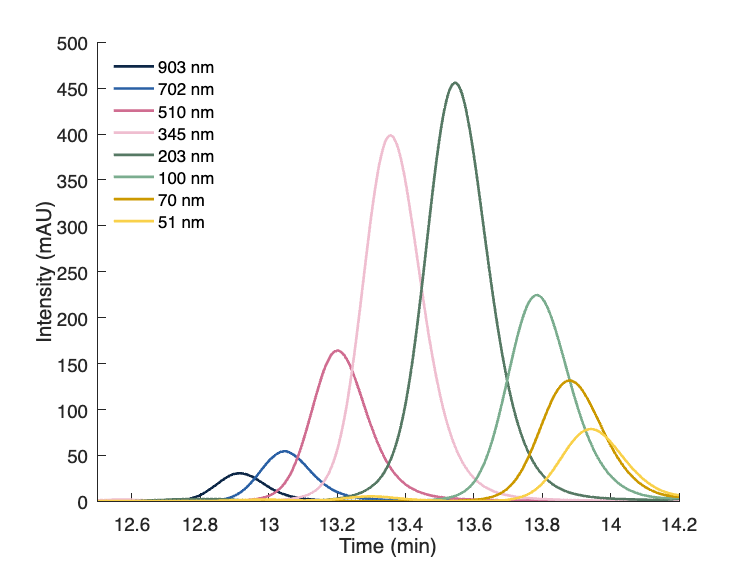

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% No need to run this %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Simulated time-I chromatograms - PLGA only
% xx = 0:(14.5/12000):14.5;    % time axis 12001 points
% figure
% hold on
% for i = 51:length(NP_info)
%     conv3(i,:) = (gauss(xx,h,tops(i),sig_cal(i)));
%     plot(xx,conv3, 'LineWidth',2)
%     set(gca, 'FontSize', 14); 
%     ax = gca; 
%     xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
%     xlim([12.5 14.5]);
% end

% hold off
% 
% % Normalized simulated chromatograms (time) 
% xx = 0:(14.5/12000):14.5;    % time axis 12001 points
% figure
% for i = 51:length(NP_info)
%     conv3_norm(i,:) = conv3(i,:)./max(conv3(i,:));
%     plot(xx,conv3_norm, 'LineWidth',2)
%     set(gca, 'FontSize', 14); 
%     ax = gca; 
%     xlabel('Time (min)'); ylabel('Normalized intensity'); 
%     xlim([12.5 14.2]);
% end
% hold on
% hold off

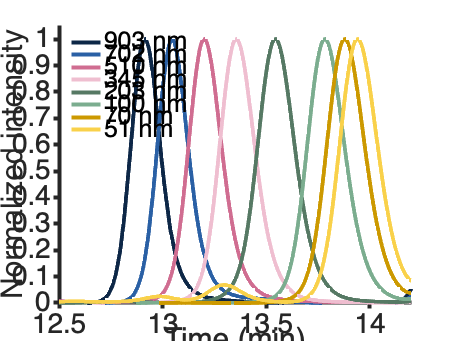

% Normalized simulated chromatograms (time)
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [62 59 56 53];
figure
hold on 
for i = 1:length(selection)
    conv3_norm = conv3(selection(i),:)./max(conv3(selection(i),:));
    plot(xx,conv3_norm, 'LineWidth',2, 'color', colors_list{(i)})
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.5 14.2]);
end
legend('422 nm', '277 nm', '229 nm', '122 nm');
legend('Location','northwest');
legend('boxoff')
hold off


## Comparison measured vs simulated chromatogram

% Plotting PS

time = PSData{1,1}(:,1);
PS_100 = [5];
PS_203 = [15];
PS_345 = [25];
PS_51 = [30];
PS_510 = [35];
PS_70 = [40];
PS_702 = [45];
PS_903 = [50];
PLGA_122 = [3];
PLGA_229 = [6];
PLGA_277 = [9];
PLGA_422 = [12];

% Short conv_norm
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
x_short = 0:(14.5/8999):14.5;    % time axis 9000 points

## Measured chromatograms

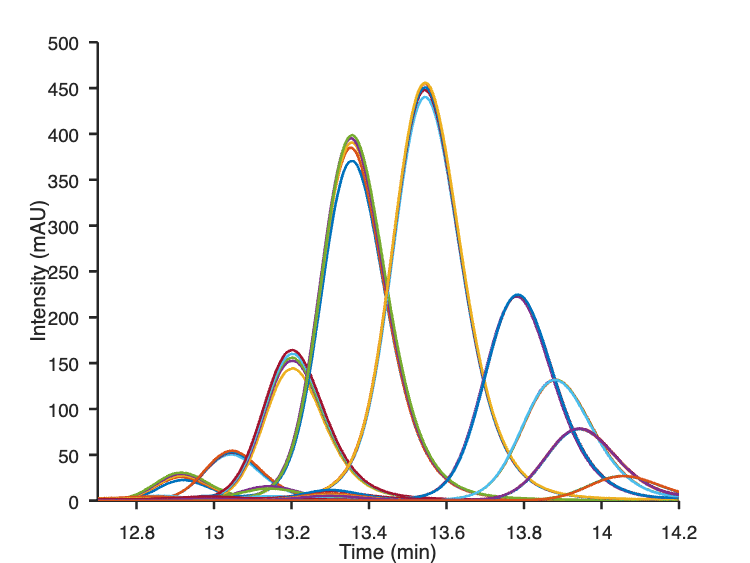

% Measured PS

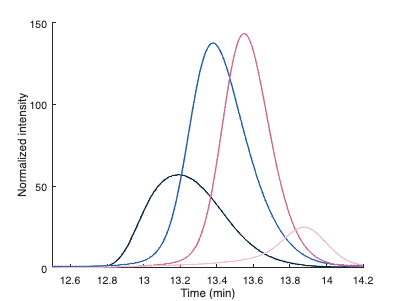

% Measured chromatograms (time)
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [50 45 35 25 15 5 40 30];
col_idx = [1 2 3 4 5 6 7 8 9 10];
figure
hold on 
for i = 1:length(selection)
    plot(time, PSData{selection(i),1}(1:9000,2), 'LineWidth',2, 'color', colors_list{(i)});
    set(gca, 'FontSize', 14); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.5 14.2]);
    ylim([0,500]);
end
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northwest');
legend('boxoff')
hold off


PSchrom_time = zeros(length(1:9000), length(PSData));
for i = 1:length(PSData)
    PS_size = PSData{i,2};
    PSchrom_time(:,i) = PS_size(1:9000,2);
end
PSchrom_time = [time PSchrom_time];

%for i = 1:length(PSData)
%    PS_chroms = PSData{selection(i),1}(1:9000,2);
%end
%PS_chroms = [time PS_chroms];

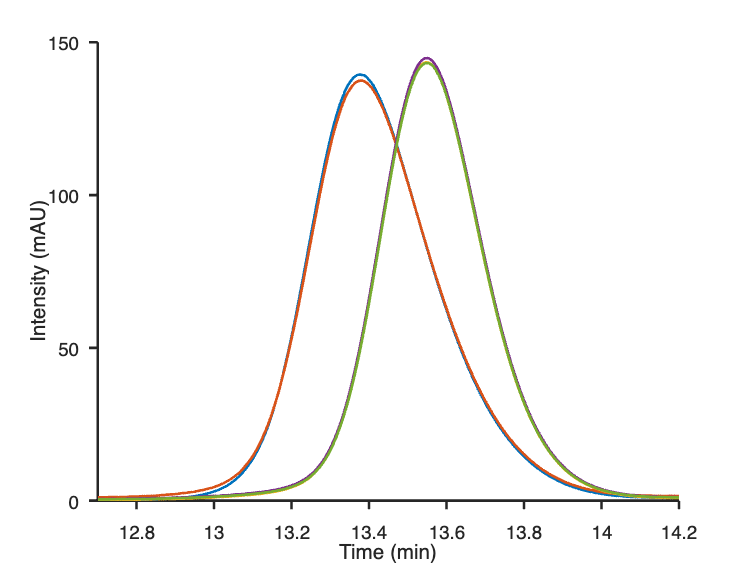

% Measured PS
% Normalized measured chromatograms (time)
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [50 45 35 25 15 5 40 30];
col_idx = [1 2 3 4 5 6 7 8 9 10];
figure
hold on 
for i = 1:length(selection)
    plot(time, PSData{selection(i),1}(1:9000,2)./max(PSData{selection(i),1}(1:9000,2)), 'LineWidth',2, 'color', colors_list{(i)});
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
    ax = gca; 
    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.5 14.2]);

    ylim([0,1.05]);
end
legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm');
legend('Location','northwest');
legend('boxoff')
hold off

% All Measured PS
% Normalized measured chromatograms (time)
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [46 47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30 16 17 18 19 20];
col_idx = [1 2 3 4 5 6 7 8 9 10];
figure
hold on 
for i = 1:length(selection)
    plot(time, PSData{selection(i),1}(1:9000,2), 'LineWidth',2);
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.7 14.2]);
    ylim([0,500]);
end
%legend('903 nm', '702 nm', '510 nm', '345 nm', '203 nm', '100 nm', '70 nm', '51 nm', '31 nm');
%legend('Location','northwest');
%legend('boxoff')
hold off

% Measured PLGA
% Normalized measured chromatograms (time)
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [12 9 6 3];
col_idx = [1 2 3 4 5 6 7 8 9 10];
figure
hold on 
for i = 1:length(selection)
    plot(time, DataPLGA{selection(i),1}(1:9000,2), 'LineWidth',2, 'color', colors_list{(i)});
    set(gca, 'FontSize', 14); 
    ax = gca; 

    xlabel('Time (min)'); ylabel('Normalized intensity'); 
    xlim([12.5 14.2]);
    ylim([0,150]);
end
hold off

PLGAchrom_time = zeros(length(1:9000), length(DataPLGA));
for i = 1:length(DataPLGA)
    PLGA_time = DataPLGA{i,2};
    PLGAchrom_time(:,i) = PLGA_time(1:9000,2);
end
PLGAchrom_time = [time PLGAchrom_time];

% Measured PLGA
% Normalized measured chromatograms (time)
colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
xx = 0:(14.5/12000):14.5;    % time axis 12001 points
selection = [8 9 4 5 6];
col_idx = [1 2 3 4 5 6 7 8 9 10];
figure
hold on 
for i = 1:length(selection)
    plot(time, DataPLGA{selection(i),1}(1:9000,2), 'LineWidth',2);
    ax = gca; 
    set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2); 
    xlabel('Time (min)'); ylabel('Intensity (mAU)'); 
    xlim([12.7 14.2]);
    ylim([0,150]);
end
hold off

## Exporting the data

names = [0 NP_info(:,1)'];
PS_names = NP_info(1:50,1)';
PLGA_names = NP_info(51:62,1)';

simulated_sizechrom = [names ; sim_size];
simulated_sizechrom_norm = [names ; sim_size_norm];

empirical_sizechrom = [names ; PSchrom_size PLGAchrom_size(:,2:13)];
empirical_sizechrom_norm = [names ; PSchrom_size_norm PLGAchrom_size_norm(:,2:13)];

simulated_timechrom = [names ; xx' conv'];

empirical_timechrom= [names ; PSchrom_time PLGAchrom_time(:,2:13)];

calibration_parameters = [p_size ; p_time];

# Peak widths

% Determination of the measured peak widths (sigma_tot_time)
% Sorting the data from large to small NPs
PS_ind = [46 47 48 49 50 41 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];
PLGA_ind = [10 11 12 7 8 9 4 5 6 1 2 3];

PS_wds = zeros(length(PS_ind),3);
for i = 1:size(PS_ind,2)
    k = PS_ind(i);
    [hgt, locs, wds] = findpeaks(PSData{k,1}(1:9000,2),time,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
    PS_wds(i,:) = [hgt(1) locs(1) wds(1)];
    PS_n(i,:) = PS_names(k);
    PS_sigma(i,:) = wds(1)/2.35;
end

PLGA_wds = zeros(length(PLGA_ind),3);
for i = 1:size(PLGA_ind,2)
    k = PLGA_ind(i);
    [hgt, locs, wds] = findpeaks(DataPLGA{k,1}(1:9000,2),time,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
    PLGA_wds(i,:) = [hgt(1) locs(1) wds(1)];
    PLGA_n(i,:) = PLGA_names(k);
    PLGA_sigma(i,:) = wds(1)/2.35;
end

PS_peak_info = [PS_n PS_wds PS_sigma PS_sigma.^2];
PLGA_peak_info = [PLGA_n PLGA_wds PLGA_sigma PLGA_sigma.^2];

NP_peak_info = [PS_peak_info ; PLGA_peak_info];
NP_peaks = NP_peak_info;            % manual outlier removal (rows 7, 43)

%res_var = NP_peaks(:,5) - NP_peaks(:,6);    % residual variance (difference measured vs system variance)
NP_BB = [NP_peaks];

% System variance
cal_sizes = NP_BB([(2:5),(7:40)],1);      % NP sizes of the PS calibrants
cal_time = NP_BB([(2:5),(7:40)],3);       % corresponding peak tops of the PS calibrants
%var_sys = NP_BB(2:39,7);        % system variance (old Stef data, not used)
sig_tot = PS_sigma([(2:5),(7:40)]);
var_tot = sig_tot.^2;

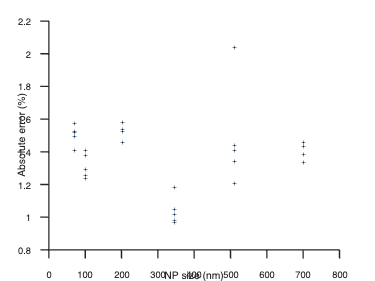

% Nino's LOO
% Own var_sys calculations
%%% These var_sys_J are based on the exact system variances per measurement
%%% >>> PS_idx indices of the PS repeats
PS_idx = [47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];
PS_group = [1 1 1 1 2 2 2 2 3 3 3 3 3 4 4 4 4 4 5 5 5 5 5 6 6 6 6 6 7 7 7 7 7 8 8 8 8 8];

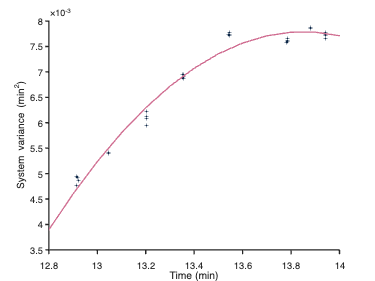

PS_rep = [1 2 3 4 1 2 3 4 1 2 3 4 5 1 2 3 4 5 1 2 3 4 5 1 2 3 4 5 1 2 3 4 5 1 2 3 4 5];
var_sys_J = zeros(length(PS_idx),1);
sig_cal = sig_cal';
var_cal = (sig_cal).^2;
for i = 1:length(PS_idx)
    for j = PS_idx(i)
        var_sys_J(i) = var_tot(i) - var_cal(j);
    end
end

% Exploration different polynomials to fit var_sys_J
p_var_2 =polyfit(cal_time,var_sys_J,2); % calculate 2nd order polynomial coordinates
%p_var_3 =polyfit(cal_time,var_sys_J,3); % calculate 3rd order polynomial coordinates
%p_var_1 =polyfit(cal_time,var_sys_J,1); % calculate 1st order polynomial coordinates

y_hat_all = polyval(p_var_2, cal_time);
All_RMSE = sqrt(mean((y_hat_all - var_sys_J).^2)); 
error_all = (y_hat_all - var_sys_J);

y_hat_LOO = [];
y_LOO = [];
for k = 2:7
    % Prepare test and train groups
    test_set = PS_idx(PS_group == k);
    train_set = PS_idx(PS_group ~= k);
    cal_time_test = cal_time(PS_group == k);
    cal_time_train = cal_time(PS_group ~=k);
    var_sys_test = zeros(length(test_set),1);      
    var_sys_train = zeros(length(train_set),1);   
    sig_cal_train = (sig_cal(PS_group ~= k));
    var_cal_train = (sig_cal_train).^2;
    sig_cal_test = (sig_cal(PS_group == k));
    var_cal_test = (sig_cal_train).^2;
    var_tot_train = var_tot(PS_group ~=k);
    var_tot_test = var_tot(PS_group ==k);
    for i = 1:length(train_set)
        for j = train_set(i)
            var_sys_train(i) = var_tot_train(i) - var_cal(j); % LOO system variance data points
        end
    end

    for i = 1:length(test_set)
       for j = test_set(i)
            var_sys_test(i) = var_tot_test(i) - var_cal(j); % data points to be predicted
       end
    end
 
    p_var_2_LOO = polyfit(cal_time_train,var_sys_train, 2);     % LOO calibration curve coordinates
    y_hat_temp = polyval(p_var_2_LOO, cal_time_test);           % LOO calibration curve
    y_hat_LOO = [y_hat_LOO; y_hat_temp];                        % LOO calibration curve in matrix
    y_LOO = [y_LOO; var_sys_test];                              % predicted system variance from test set
end


LOO_RMSE = sqrt(mean((y_hat_LOO - y_LOO).^2)); 
error_LOO = y_hat_LOO - y_LOO;


% Plotting the absolute difference between normal error and LOO error
figure
hold on
error_abs = abs(error_all(5:end-5) - error_LOO./error_all(5:end-5));
calibrant_names = [702 702 702 702 510 510 510 510 510 345 345 345 345 345 203 203 203 203 203 100 100 100 100 100 70 70 70 70 70]';
plot(calibrant_names, error_abs,'*','MarkerSize',7,'color','#0D2747')
hold off
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('NP size (nm)'); ylabel('Absolute error (%)'); 

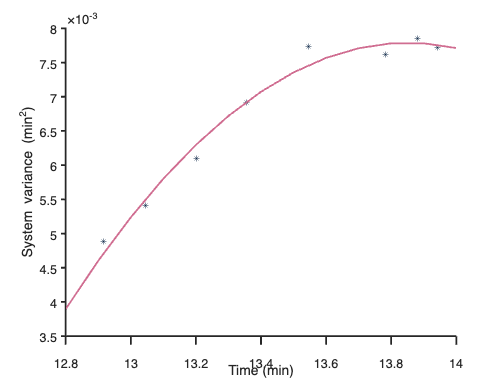

% Var_sys calibration, without LOO
%%% These var_sys_J are based on the exact system variances per measurement
%%% >>> PS_idx indices of the PS repeats
PS_idx = [47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];

var_sys_J = zeros(length(PS_idx),1);
sig_cal = sig_cal';

var_cal = (sig_cal).^2;
for i = 1:length(PS_idx)
    for j = PS_idx(i)
        var_sys_J(i) = var_tot(i) - var_cal(j);
    end
end

% Exploration different polynomials to fit var_sys_J
p_var_2 =polyfit(cal_time,var_sys_J,2); % calculate 2nd order polynomial coordinates
%p_var_3 =polyfit(cal_time,var_sys_J,3); % calculate 3rd order polynomial coordinates
%p_var_1 =polyfit(cal_time,var_sys_J,1); % calculate 1st order polynomial coordinates

colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
time_range = 12.5:0.01:14.5;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% No need to run this %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2nd vs 1st order polynomial
% figure
% hold on
% plot(cal_time, var_sys_J,'*','color',colors_list{1},'MarkerSize', 7)
% plot(time_range, polyval(p_var_2,time_range), 'color', colors_list{3}, 'linewidth', 2)
% plot(time_range, polyval(p_var_1,time_range), 'color', colors_list{4}, 'linewidth', 2)
% set(gca, 'FontSize', 14); 
% ax = gca;
% xlabel('Time (min)'); ylabel('System variance (min)'); 
% xlim([12.8 14]);
% legend('PS', '2nd order', '1st order')
% legend('boxoff')
% legend('location','northwest')
% hold off

% System variance plot

figure
hold on
plot(cal_time, var_sys_J,'*','color',colors_list{1},'MarkerSize', 7)
plot(time_range, polyval(p_var_2,time_range), 'color', colors_list{3}, 'linewidth', 2)
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('System variance (min^{2})'); 
xlim([12.8 14]);
%legend('PS', 'variance trend')
%legend('boxoff')
%legend('location','northwest')
hold off

%%% Averages calculated in Excel
%%% Without 900 nm outlier (in width)
cal_time_avg = [12.91750073 13.04583359 13.20233364 13.35466709 13.54466763 13.78300056 13.88066692 13.94233398];
var_sys_avg = [0.004878472 0.005407269 0.006101796 0.006920077 0.007737579 0.007621984 0.007858044 0.007719673];
var_sys_std = [8.05208E-05 9.08629E-06 0.000104224 3.72159E-05 2.58553E-05 3.54182E-05 9.38124E-06 4.22937E-05];

colors_list = {'#0D2747' '#2A60A5' '#D06D91' '#EFBED0' '#567964' '#7BAD8F' '#CC9900' '#F9D14A' '#F9D14A' '#0D2747'};
figure
hold on
plot(cal_time_avg, var_sys_avg,'*','color',colors_list{1},'MarkerSize', 7)
plot(time_range, polyval(p_var_2,time_range), 'color', colors_list{3}, 'linewidth', 2)
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('System variance (min^{2})'); 
xlim([12.8 14]);
%legend('PS', 'variance trend')
%legend('boxoff')
%legend('location','northwest')
hold off

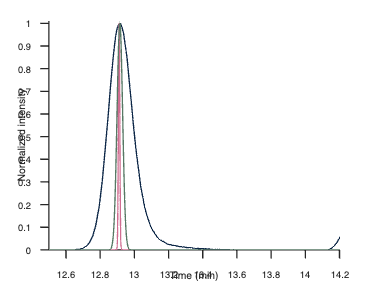

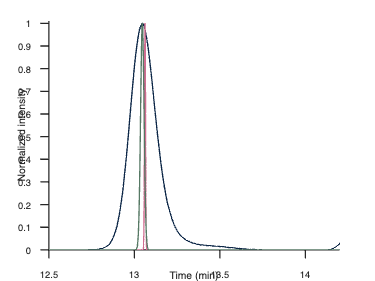

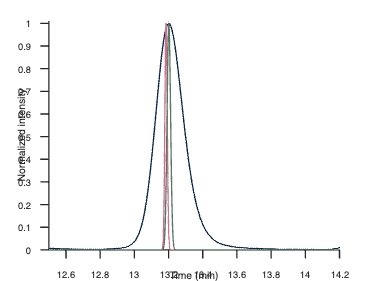

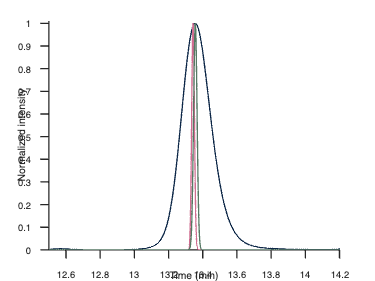

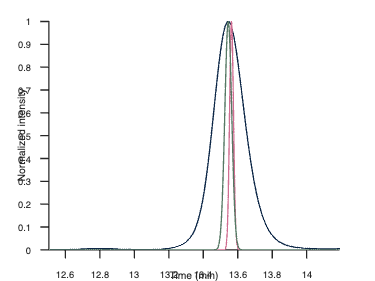

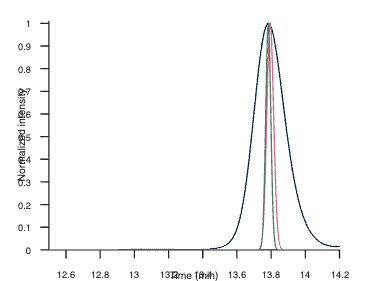

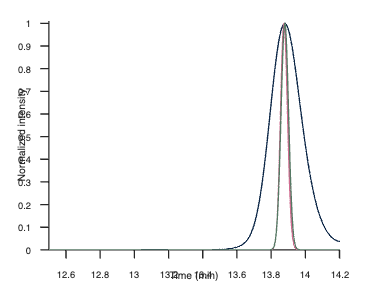

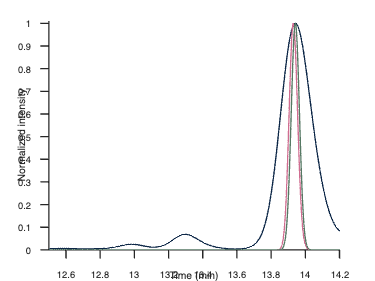

% Peak variance corrected for system variance at specific time point
%var_sys_fit = polyval(p_var_2,cal_time); %%%%%% fitted system variance -> negative peak widths
var_sys_fit_temp = polyval(p_var_2,cal_time);

%%% This var_res is based on the var_sys per measurement
%var_res = var_tot - var_sys_J;  % peak variance corrected for system variance

% Calculated with Excel sheet
%%% These var_res are based on the calibrated var_sys; restricted that if
%%% var_tot < LOD
var_res = [0.0001042
0.0001324
0.0002197
0.0002674
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042
0.0001042

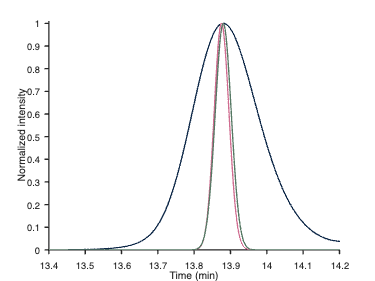

0.0001042
0.0001042
0.0001050
0.0001042
0.0003788
0.0004003
0.0004053
0.0004486
0.0003998
0.0002021
0.0002745
0.0002395
0.0002833
0.0002175
0.0005045
0.0004889
0.0004792
0.0004863
0.0004848

0.0006241
0.0005059
0.0005767
0.0005680
0.0005773];

sig_res = sqrt(var_res);        % resulting sigma in min 

NP_BB_PS = [NP_BB([2:5,7:40],:) var_res sig_res];

## Establish certified size chromatograms

Similar as beginning of script, but in correct dimensions for comparison measured vs corrected

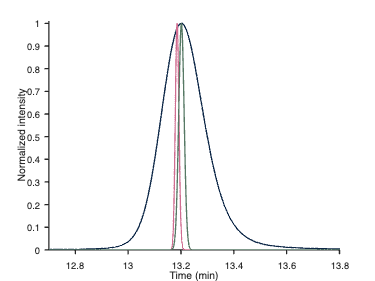

% Certified size chromatograms
PS_samples = [50 45 35 25 15 5 40 30];
x = 0:(1/7.5):1200; % x-axis in size
x = x';
size_x = x(1:end-1,:); % x-axis in size in right dimensions
time_x = polyval(p_time,size_x);
h = 1;
cert_chrom_s = zeros(length(time),length(PS_samples));
for i = 1:length(PS_samples) % number of PS standards
    for j = PS_samples(i)    % specific PS sample (5th run of each sample)

        cert_chrom_s(:,i) = gauss(size_x,1,NP_info(j,1),NP_info(j,2)); % certified size chromatograms
    end
end
cert_chrom_sn = cert_chrom_s./max(cert_chrom_s); % normalized certified size chromatograms



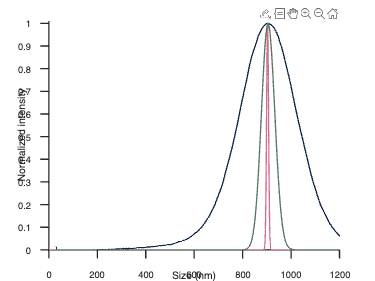

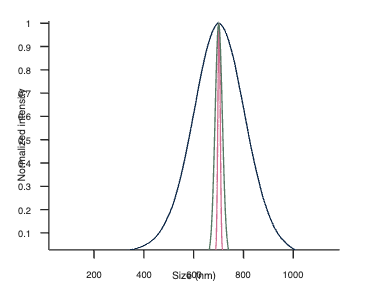

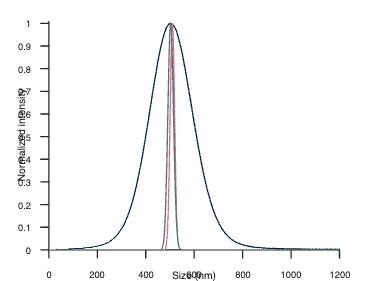

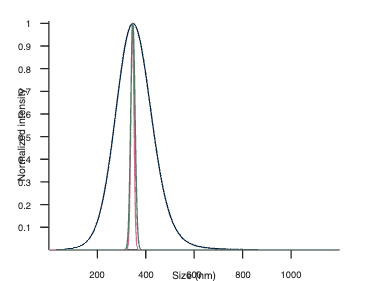

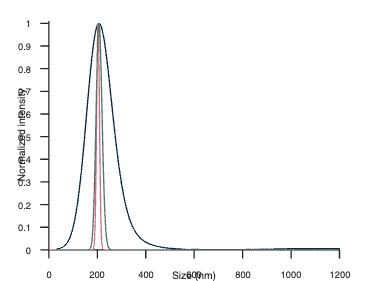

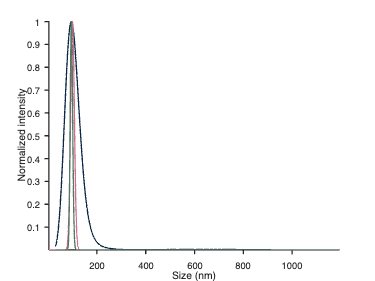

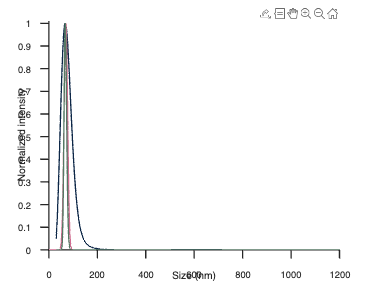

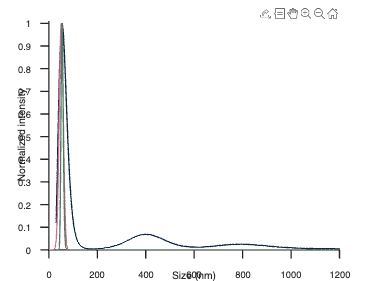

% Overview time chromatograms
% Comparison measured (blue), ideal (pink) and corrected (green) chromatograms
PS_samples = [50 45 35 25 15 5 40 30];
%PS_cor = [5 9 14 19 24 29 34 39];
PS_cor = [4 8 13 18 23 28 33 38];
PScor_t_wds = zeros(1,length(PS_samples));
PScor_t_sigma = zeros(1,length(PS_samples));
cor_t_matrix = zeros(length(time),length(PS_samples));
PS_title = {'PS 903 nm' 'PS 702 nm' 'PS 510 nm' 'PS 345 nm' 'PS 203 nm' 'PS 100 nm' 'PS 70 nm' 'PS 51 nm'};
for i = 1:length(PS_samples)
    for j = PS_samples(i)
        for k = PS_cor(i)
            figure
            hold on
            plot(time,PSData{j,1}(1:9000,2)./max(PSData{j,1}(1:9000,2)),'LineWidth',2,'color', colors_list{1}); % measured chrom
            %title(PS_title{i});
            plot(time_x,cert_chrom_sn(:,i),'LineWidth',2,'color','#D06D91') % certified chrom
            cor_t = gauss(time,NP_BB_PS(k,2),NP_BB_PS(k,3),sig_res(k));
            cor_t_matrix(:,i) = gauss(time,NP_BB_PS(k,2),NP_BB_PS(k,3),sig_res(k));
            plot(time,cor_t./max(cor_t), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
            ax = gca;
            set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
            xlabel('Time (min)'); ylabel('Normalized intensity'); 
            xlim([12.5 14.2]);
            ylim([0 1.01]);
            hold off
            [hgt, locs, wds] = findpeaks(cor_t,time,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');

            PScor_t_sigma(:,i) = wds/2.35;
        end
    end
end

PScor_t_sigma = PScor_t_sigma'; %%% sigma only for plotted peaks
cor_t_n = cor_t_matrix./max(cor_t_matrix);

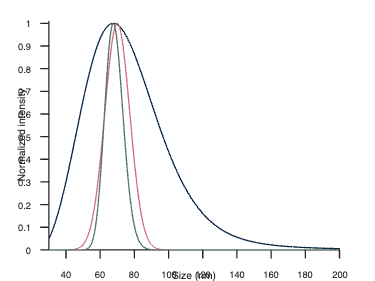

% Example time chromatogram PS 70 nm
figure
hold on
plot(time,PSData{40,1}(1:9000,2)./max(PSData{40,1}(1:9000,2)),'LineWidth',2,'color', colors_list{1}); % measured chrom
%sim(40,:) = gauss(x_short,h,tops(40),sig_cal(40)); % simulated chrom
%sim_norm(40,:) = sim(40,:)./max(sim(40,7500:9000));
plot(time_x,cert_chrom_sn(:,7),'LineWidth',2,'color','#D06D91')
cor_t = gauss(time,NP_BB_PS(33,2),NP_BB_PS(33,3),sig_res(33));

plot(time,cor_t./max(cor_t), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([13.4 14.2]);
ylim([0 1.01]);
hold off
%legend('Measured','Certified','Corrected');
%legend('boxoff')
%legend('location','northeast')


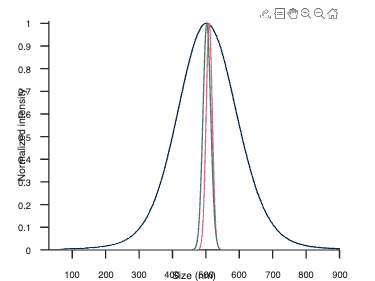

% Example time chromatogram PS 510 nm
figure
hold on
plot(time,PSData{35,1}(1:9000,2)./max(PSData{35,1}(1:9000,2)),'LineWidth',2,'color', colors_list{1}); % measured chrom
%sim(35,:) = gauss(x_short,h,tops(35),sig_cal(35)); % simulated chrom
%sim_norm(35,:) = sim(35,:)./max(sim(35,7500:9000));

plot(time_x,cert_chrom_sn(:,3),'LineWidth',2,'color','#D06D91')
cor_t = gauss(time,NP_BB_PS(13,2),NP_BB_PS(13,3),sig_res(13));
plot(time,cor_t./max(cor_t), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Time (min)'); ylabel('Normalized intensity'); 
xlim([12.7 13.8]);
ylim([0 1.01]);
hold off
%legend('Measured','Certified','Corrected');
%legend('boxoff')
%legend('location','northeast')

% Size chromatograms
x_size = polyval(p_size,time);
size_loc = polyval(p_size,NP_BB_PS(:,3));
sig_res_s = polyval(p_size,sig_res);
%PScor_size_sigma = zeros(1, length(PS_all));

for i = 1:length(PS_samples)
    for j = PS_samples(i)
        for k = PS_cor(i)
            figure
            hold on
            max_val = max(PSData{j,1}(7500:8500,2));
            plot(x_size(7500:8500),(PSData{j,1}(7500:8500,2)./max_val),'LineWidth',2,'color', colors_list{1}) % measured chrom
            plot(size_x,cert_chrom_sn(:,i),'LineWidth',2,'color','#D06D91') % certified chromatogram
            plot(x_size(7500:8500),cor_t_n(7500:8500,i), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
            %title(PS_title{i});
            ax = gca;
            set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
            xlabel('Size (nm)'); ylabel('Normalized intensity'); 
            xlim([0 1200]);
            ylim([0 1.01]);
            hold off
            [hgt, locs, wds] = findpeaks(flip(cor_size(7500:8500)),flip(x_size(7500:8500)),'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
            %PScor_size_sigma(:,i) = wds/2.35;
            %[hgt2, locs2, wds2] = findpeaks(flip(PSData{j,1}(7500:8500,2)),flip(x_size(7500:8500)),'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
            %PSemp_size_sigma(:,i) = wds2(1)/2.35;
        end
    end
end
%PScor_size_sigma = PScor_size_sigma';

% Example size chromatogram with legend, 70 nm
figure
hold on
max_val = max(PSData{40,1}(7500:8500,2));
plot(x_size(7500:8500),(PSData{40,1}(7500:8500,2)./max_val),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(size_x,cert_chrom_sn(:,7),'LineWidth',2,'color','#D06D91') % certified chromatogram
plot(x_size(7500:8500),cor_t_n(7500:8500,7), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([30 200]);
ylim([0 1.01]);
hold off
%legend('Measured','Certified','Corrected');
%legend('boxoff')
%legend('location','northeast')

% Example size chromatogram with legend, 510 nm
figure
hold on
max_val = max(PSData{34,1}(7500:8500,2));
plot(x_size(7500:8500),(PSData{34,1}(7500:8500,2)./max_val),'LineWidth',2,'color', colors_list{1}) % measured chrom
plot(size_x,cert_chrom_sn(:,3),'LineWidth',2,'color','#D06D91') % certified chromatogram
plot(x_size(7500:8500),cor_t_n(7500:8500,3), 'LineWidth',2,'color', colors_list{5}) % corrected chrom
ax = gca;
set(gca, 'FontSize', 14, 'TickDir','out','LineWidth',2);
xlabel('Size (nm)'); ylabel('Normalized intensity'); 
xlim([30 900]);
ylim([0 1.01]);
hold off
%legend('Measured','Certified','Corrected');
%legend('boxoff')
%legend('location','northeast')

## Peak widths of size-converted measured chromatograms

% Calculate peak widths of the measured size-chromatograms
PS_idx = [47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];
PS_emp_size_sigma = zeros(1,length(NP_BB_PS));
PS_emp_size_tops = zeros(1,length(NP_BB_PS));
for i = 1:length(NP_BB_PS)
    for j = PS_idx(i)
        %plot(size(7500:8500),(PSData{j,1}(7500:8500,2)),'LineWidth',2,'color', colors_list{1}) % measured chrom
        [hgt2, locs2, wds2] = findpeaks(flip(PSData{j,1}(7500:8500,2)),flip(x_size(7500:8500)),'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
        PS_emp_size_sigma(:,i) = wds2(1)./2.35;
        PS_emp_size_tops(:,i) = locs2(1);
    end
end 
PS_emp_size_sigma = PS_emp_size_sigma';
PS_emp_size_tops = PS_emp_size_tops';

## Peak widths of time-converted certified chromatograms

PS_all = [47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];
cert_sig_t = zeros(length(PS_all),1);
for i = 1:length(PS_all)
    for j = PS_all(i)
        %cert_chrom_t = gauss(time, 1, cal_overview(j,2), cal_overview(j,3));
        cert_sig_t(i) = cal_overview(j,3);
    end
end


## Peak widths of corrected chromatograms

% Corrected time-chromatograms
PScor_t_wds = zeros(length(NP_BB_PS),1);
PScor_t_sigma = zeros(length(NP_BB_PS),1);

for i = 1:length(NP_BB_PS)
    cor_t(:,i) = gauss(time,NP_BB_PS(i,2),NP_BB_PS(i,3),sig_res(i)); % corrected time chrom
    [hgt_t, locs_t, wds_t] = findpeaks(cor_t(:,i),time,'MinPeakHeight',1, 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
    PScor_t_sigma(i) = [wds_t/2.35];
end
cor_tn = cor_t./max(cor_t); % normalized corrected time chrom

% Corrected size-chromatograms
size_x = x(1:end-1,:); % x-axis in size in right dimensions
%PS_all = [46 47 48 49 50 42 43 44 45 31 32 33 34 35 21 22 23 24 25 11 12 13 14 15 1 2 3 4 5 36 37 38 39 40 26 27 28 29 30];
PScor_s_wds = zeros(length(NP_BB_PS),1);
PScor_s_sigma = zeros(length(NP_BB_PS),1);
for i = 1:length(NP_BB_PS)
    cor_t_all(:,i) = gauss(time,1,NP_BB_PS(i,3),sig_res(i));
    cor_size_ax = polyval(p_size,time);
    [hgt_s, locs_s, wds_s] = findpeaks(flip(cor_t_all((7500:8500),i)),flip(cor_size_ax(7500:8500)), 'Annotate', 'extents', 'WidthReference', 'halfheight','SortStr','descend');
    PScor_s_sigma(i) = [wds_s/2.35];
end
%cor_sn = cor_s./max(cor_s); % normalized corrected size chrom


%plot(x_size(7500:8500),cor_t_n(7500:8500,i),

# Data exportation

Makes an overview of the following parameters:

- NP size (mu) - size

- Measured peak height - time

- Measured peak top - time

- Measured FWHM - time

- Measured sigma - time

- Measured variance - time

- System variance - time

- Residual variance - time

- Measured size - size

- Measured sigma - size

- Corrected sigma - time

- Corrected sigma - size

- Certified sigma - time

% Prepare 1 matrix with all PS info (without first 702 nm outlier, line 6 in PS_peak_info)
PS_matrix = [PS_peak_info([(2:5),(7:end)],:) var_sys_J var_res PS_emp_size_tops PS_emp_size_sigma PScor_t_sigma PScor_s_sigma cert_sig_t];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% No need to run this %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PLGA_all = [10 12 7 8 9 4 5 6 1 2 3];
% PLGA_all_chroms = zeros(9000,length(PLGA_all));
% for i = 1:length(PLGA_all)
%     for j = PLGA_all(i)
%         PLGA_all_chroms(:,i) = DataPLGA{j,1}(1:9000,2);
%     end
% end
% 
% PLGA_all_chroms = [time, PLGA_all_chroms];

%%

# UV correction

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% No need to run this %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Parameters UV correction
% h = 473.2121292; % peak height
% p = 13.49695081; % peak position
% w = 0.315944102; % peak sigma
% m = 998.4956319; % shape factor
% e = 0.047121311; % asymmetry factor

